% FM Code
clear all; clc; clf;
% INSTRUCTIONS

### Modulation

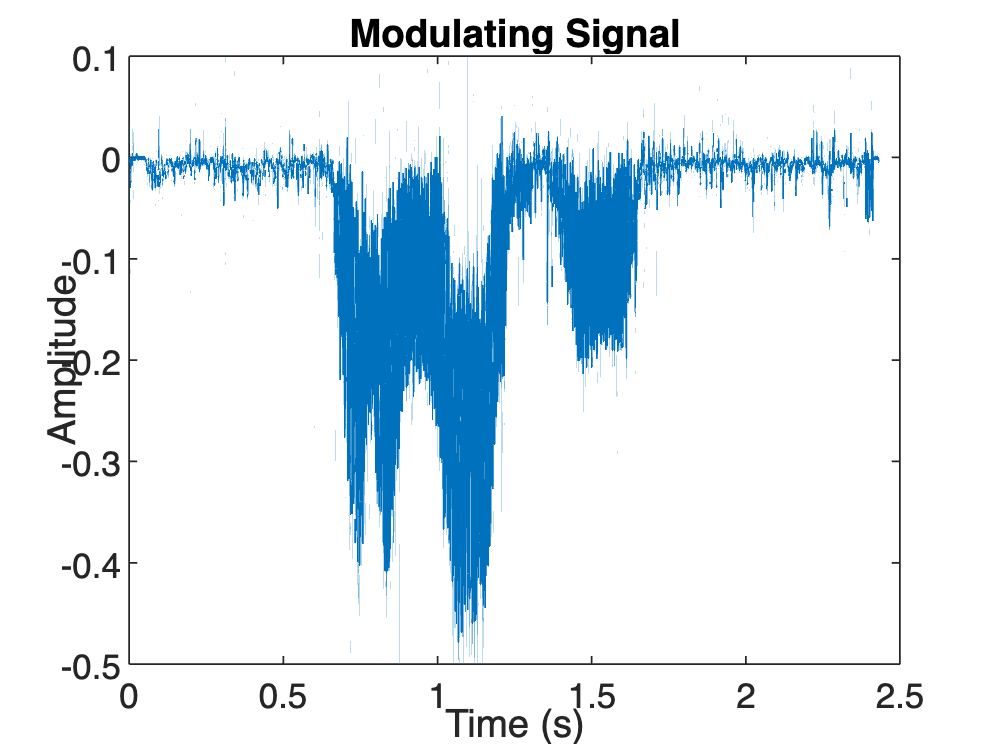

% Step 1: Generate a modulating signal
[y, Fs] = audioread('New-Recording.wav');
% scope = spectrumAnalyzer(SampleRate = Fs);
t = linspace(0, length(y)/Fs, length(y));
figure;
plot(t, y);
xlabel('Time (s)');
ylabel('Amplitude');
title('Modulating Signal');

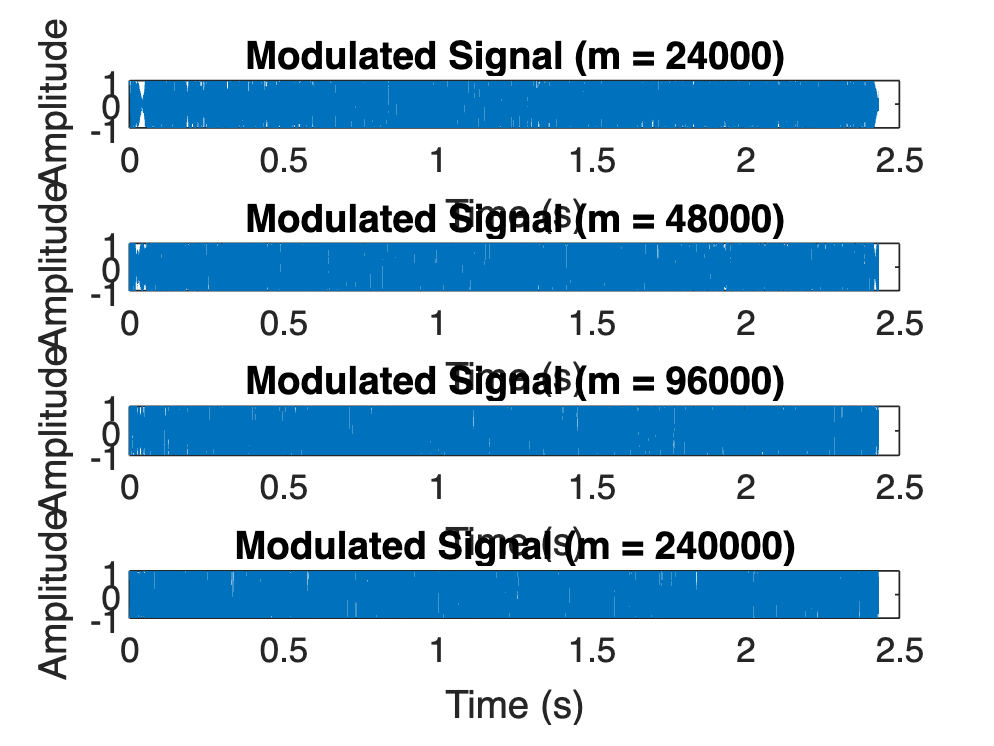

% Step 2: Apply Frequency Modulation
Fc = Fs/2; % Carrier frequency

% Set frequency deviations under test
devf1 = Fs*0.5;
devf2 = Fs*1;
devf3 = Fs*2;
devf4 = Fs*5;

% Apply frequency modulation
y_fmmod1 = fmmod(y,Fc,Fs,devf1);
y_fmmod2 = fmmod(y,Fc,Fs,devf2);
y_fmmod3 = fmmod(y,Fc,Fs,devf3);
y_fmmod4 = fmmod(y,Fc,Fs,devf4);

figure;
subplot(411)
plot(t, y_fmmod1); xlabel('Time (s)'); ylabel('Amplitude');
title(['Modulated Signal (m = ' num2str(devf1) ')']);
subplot(412)
plot(t, y_fmmod2); xlabel('Time (s)'); ylabel('Amplitude');
title(['Modulated Signal (m = ' num2str(devf2) ')']);
subplot(413)
plot(t, y_fmmod3); xlabel('Time (s)'); ylabel('Amplitude');
title(['Modulated Signal (m = ' num2str(devf3) ')']);
subplot(414)
plot(t, y_fmmod4); xlabel('Time (s)'); ylabel('Amplitude');
title(['Modulated Signal (m = ' num2str(devf4) ')']);

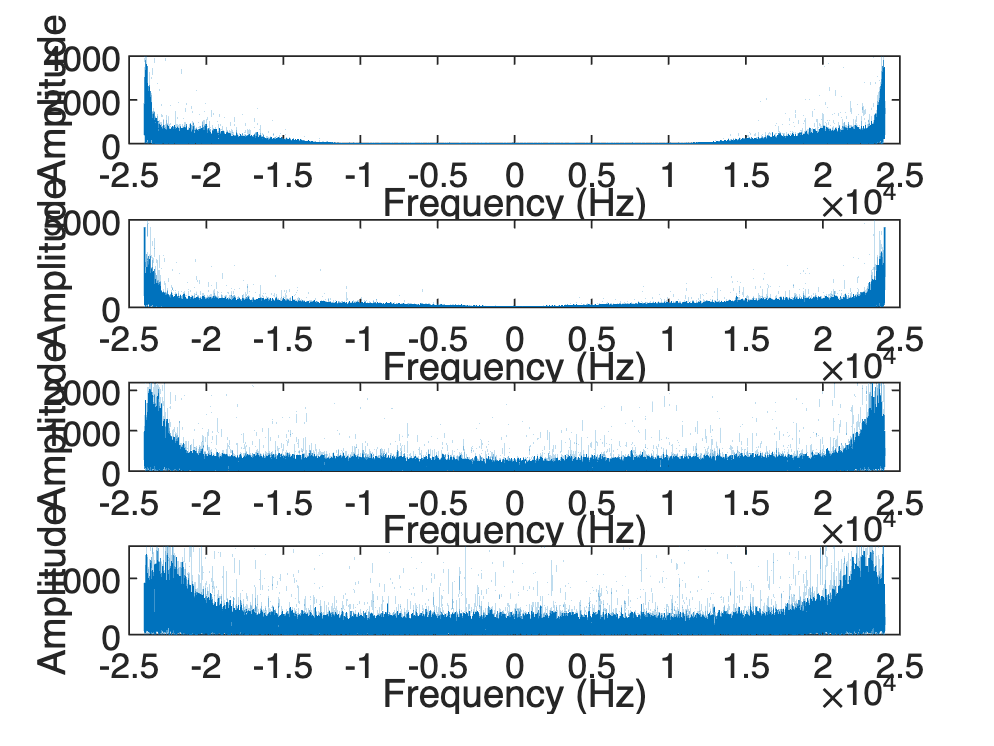

figure;
subplot(411)
fftplot(y_fmmod1,Fs)
subplot(412)
fftplot(y_fmmod2,Fs)
subplot(413)
fftplot(y_fmmod3,Fs)
subplot(414)
fftplot(y_fmmod4,Fs)

% Step 3: Amplify the modulated signals
Gfm = 100;
y_afmmod1 = Gfm*y_fmmod1;
y_afmmod2 = Gfm*y_fmmod2;
y_afmmod3 = Gfm*y_fmmod3;
y_afmmod4 = Gfm*y_fmmod4;

#### During Transmission

% Step 4: Add noise

% Define SNR values (in dB)
snr1 = 0;
snr2 = 2;
snr3 = 5;
snr4 = 10;
snr5 = -2;
snr6 = -5;
snr7 = -10;

% Apply additive white gaussian noise
y_nafmmod11 = awgn(y_afmmod1,snr1);
y_nafmmod12 = awgn(y_afmmod2,snr2);
y_nafmmod13 = awgn(y_afmmod3,snr3);
y_nafmmod14 = awgn(y_afmmod4,snr4);

### Demodulation

% Step 5: Demodulate
y_fmdemod1 = fmdemod(y_nafmmod11,Fc,Fs,devf1);
y_fmdemod2 = fmdemod(y_nafmmod12,Fc,Fs,devf2);
y_fmdemod3 = fmdemod(y_nafmmod13,Fc,Fs,devf3);
y_fmdemod4 = fmdemod(y_nafmmod14,Fc,Fs,devf4);

% Design filter
n = 2;
Rs = 20;
Ws = 0.075;
[b,a] = cheby2(n,Rs,Ws);

% Apply filter
y_ffmdemod1 = filter(b,a,y_fmdemod1);
y_ffmdemod2 = filter(b,a,y_fmdemod2);
y_ffmdemod3 = filter(b,a,y_fmdemod3);
y_ffmdemod4 = filter(b,a,y_fmdemod4);

% Write audio signals
audiowrite("New-RecordingFMDEMOD1.wav",y_ffmdemod1,Fs);
audiowrite("New-RecordingFMDEMOD2.wav",y_ffmdemod2,Fs);
audiowrite("New-RecordingFMDEMOD3.wav",y_ffmdemod3,Fs);
audiowrite("New-RecordingFMDEMOD4.wav",y_ffmdemod4,Fs);

function fftplot(signal,Fs)
    [N,~] = size(signal);
    t = -Fs/2:Fs/(N-1):Fs/2;
    signalfreq = fftshift(fft(signal));
    plot(t,abs(signalfreq)); xlabel("Frequency (Hz)"); ylabel("Amplitude"); 
end